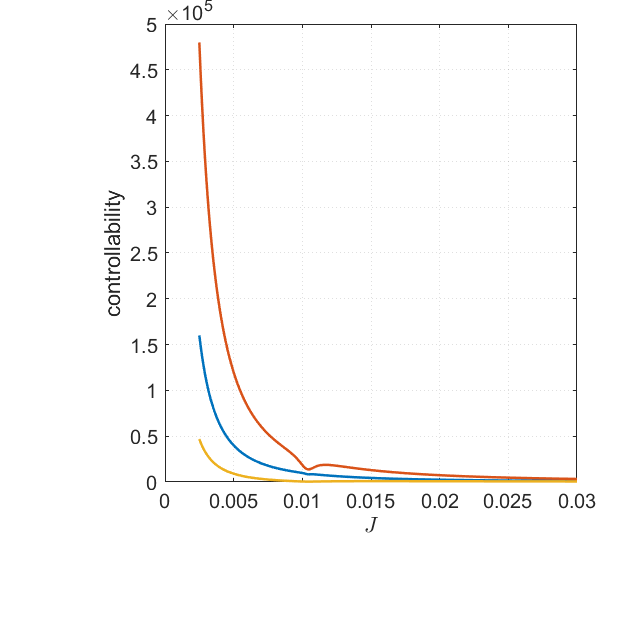

J_z = 0.0104;
kr = 0.001;
omega_0z = -20;

J = 0.0025:0.0001:0.03;

[~,imax] = size(J);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg3(J_z, J(i), omega_0z, kr,1);
end
figure(1)
clf
plot(J,p1,J,p2,J,p3,'LineWidth',1.5)
xlabel('$J$','Interpreter',"latex")
ylabel('controllability')

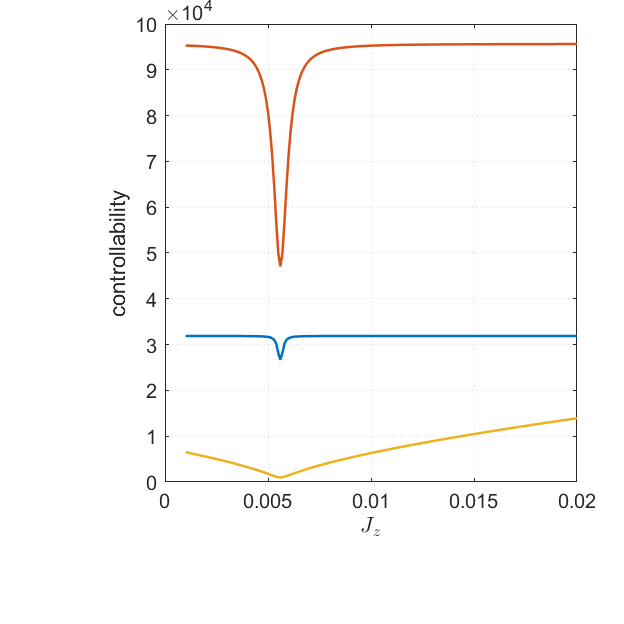

kr = 0.001;
omega_0z = -20;
J=0.0056;

J_z = 0.0010:0.0001:0.02;
[~,imax] = size(J_z);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg3(J_z(i), J, omega_0z, kr,1);
end
figure(2)
clf
plot(J_z,p1,J_z,p2,J_z,p3,'LineWidth',1.5)
xlabel('$J_z$','Interpreter',"latex")
ylabel('controllability')

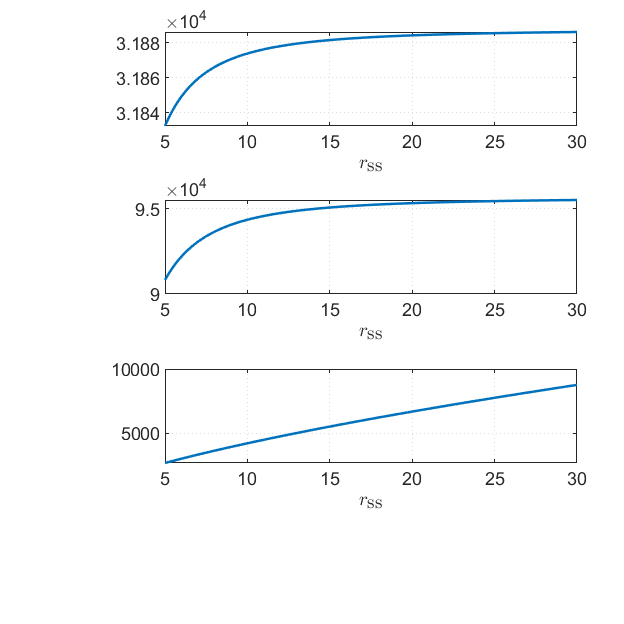

kr = 0.001;
% omega_0z = -20;
J=0.0056;
J_z = 0.0104;

omega_0z = 5:0.1:30;
[~,imax] = size(omega_0z);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg3(J_z, J, omega_0z(i), kr,1);
end
figure(3)
clf
subplot(3,1,1)
plot(omega_0z,p1,'LineWidth',1.5)
xlabel('$r_{\textrm{ss}}$','Interpreter',"latex")
subplot(3,1,2)
plot(omega_0z,p2,'LineWidth',1.5)
xlabel('$r_{\textrm{ss}}$','Interpreter',"latex")
subplot(3,1,3)
plot(omega_0z,p3,'LineWidth',1.5)
xlabel('$r_{\textrm{ss}}$','Interpreter',"latex")

20220330重构可控度的图画

s = figure(6)

s =   Figure (6) - 属性:

      Number: 6
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [0 0 13.2000 13.2000]
       Units: 'centimeters'

  显示 所有属性


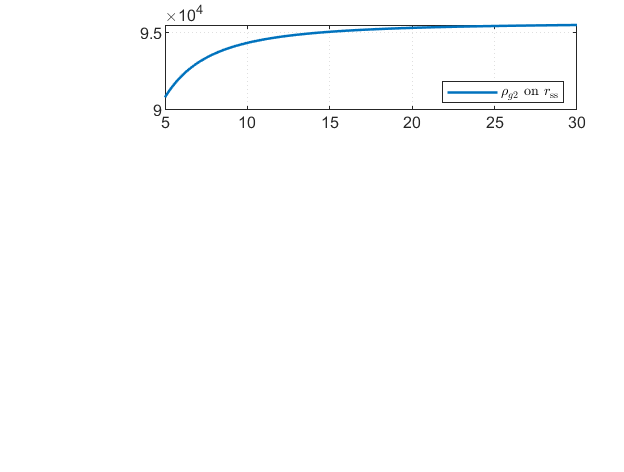

s.Position = [0,0,13.2,10];
clf
p = subplot(3,1,1);
p.Position(4) = 0.1800;
plot(omega_0z,p2,'LineWidth',1.5)
% xlabel('$r_{\mathrm{ss}}$','Interpreter',"latex")
legend("$\rho_{g2}$ on $r_{\mathrm{ss}}$",'Interpreter',"latex")

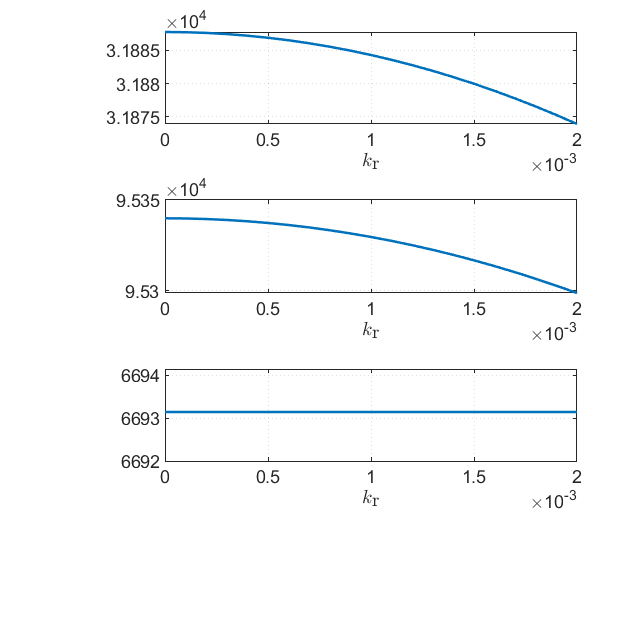

% kr = 0.001;
omega_0z = -20;
J=0.0056;
J_z = 0.0104;

kr = 0.0000:0.0001:0.002;
[~,imax] = size(kr);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg3(J_z, J, omega_0z, kr(i),1);
end
figure(4)
clf
subplot(3,1,1)
plot(kr,p1,'LineWidth',1.5)
xlabel('$k_{\textrm{r}}$','Interpreter',"latex")
subplot(3,1,2)
plot(kr,p2,'LineWidth',1.5)
xlabel('$k_{\textrm{r}}$','Interpreter',"latex")
subplot(3,1,3)
plot(kr,p3,'LineWidth',1.5)
xlabel('$k_{\textrm{r}}$','Interpreter',"latex")

20220330重构可控度的图画

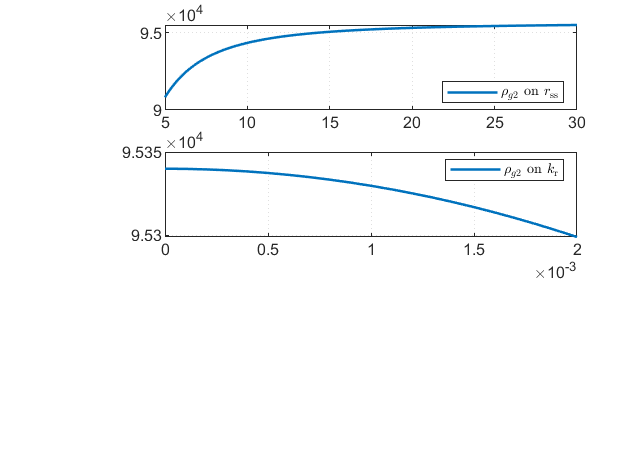

figure(6)
p = subplot(3,1,2);
p.Position(4) = 0.1800;
plot(kr,p2,'LineWidth',1.5)
% xlabel('$k_{\mathrm{r}}$','Interpreter',"latex")
legend("$\rho_{g2}$ on $k_{\mathrm{r}}$",'Interpreter',"latex",'Location',"northeast")

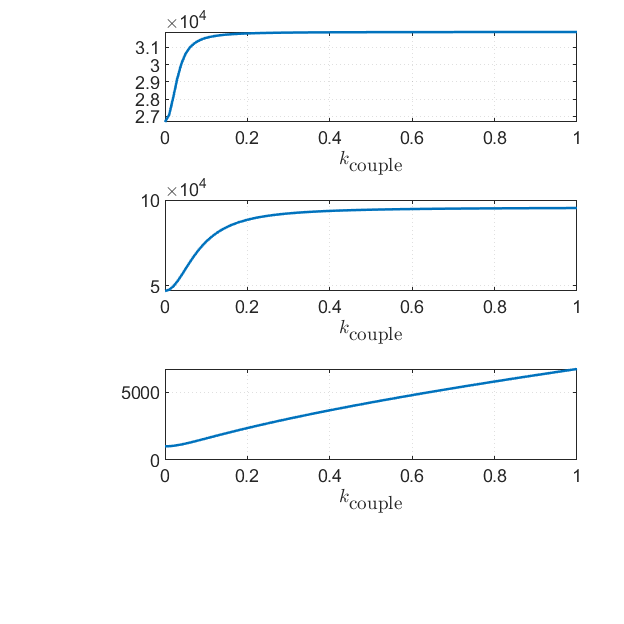

kr = 0.001;
omega_0z = -20;
J=0.0056;
J_z = 0.0104;

kcp = 0.0:0.01:1.0;
[~,imax] = size(kcp);
p1 = zeros(1,imax);
p2 = zeros(1,imax);
p3 = zeros(1,imax);
for i=1:imax
[p1(i), p2(i), p3(i)] = controldeg3(J_z, J, omega_0z, kr,kcp(i));
end
figure(3)
clf
subplot(3,1,1)
plot(kcp,p1,'LineWidth',1.5)
xlabel('$k_{\textrm{couple}}$','Interpreter',"latex")

subplot(3,1,2)
plot(kcp,p2,'LineWidth',1.5)
xlabel('$k_{\textrm{couple}}$','Interpreter',"latex")

subplot(3,1,3)
plot(kcp,p3,'LineWidth',1.5)
xlabel('$k_{\textrm{couple}}$','Interpreter',"latex")

20220330重构可控度的图画

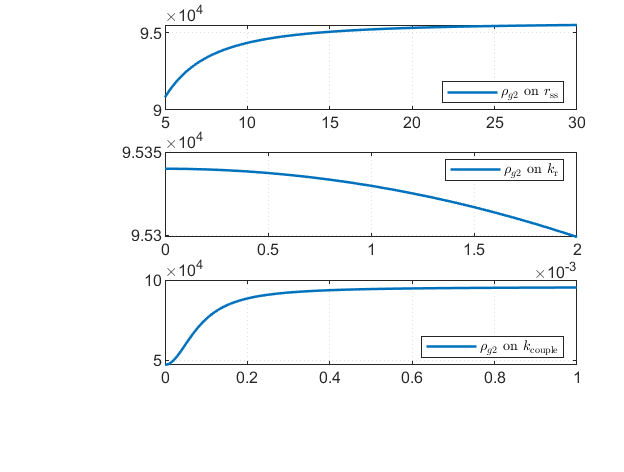

figure(6)
p = subplot(3,1,3);
p.Position(4) = 0.1800;
plot(kcp,p2,'LineWidth',1.5)
% xlabel('$k_{\mathrm{couple}}$','Interpreter',"latex")
legend("$\rho_{g2}$ on $k_{\mathrm{couple}}$",'Interpreter',"latex")